Get the parameters:

[input, fname, fs2, type_signal, fs1, T, periodicity, frequencies,...
spectral_resolution, window, overlapSTFT, filterType, order, method, type, cutoffFrequencies , ...
xlimTime, ylimAmplitude, xAxisType, yAxisType,xlimFreq, ylimFreq] ...
=specs()

Reading line: "%% This is the specification file for the assingnment project in 22051."
Reading line: "% Use input signal or generated signal? Possible: wav, generate (variable name= input)"
Reading line: "wav"
Reading line: "% WAV-filename (variable name= fname)"
Reading line: "mini-me_short.wav"
Reading line: "% Target sampling frequency (Hz) of the .wav file (variable name= fs2)"
Reading line: "10000"
Reading line: "% SIGNAL GENERATOR"
Reading line: "% Type of signal. Possible: rect, tone, tone-complex, noise (variable name= type_signal)"
Reading line: "tone-complex"
Reading line: "% Sampling frequency (Hz) (variable name= fs1)"
Reading line: "20000"
Reading line: "% Overall duration of the signal (in s) (variable name= T)"
Reading line: "4"
Reading line: "% Periodicity (s) - only applicable for "rect". The width of each rectangle should be half the period. (variable name= periodicity)"
Reading line: "0.5"
Reading line: "% Frequency/-ies of the tone/tone complex (only first if 'tone

input = 'wav'

fname = 'mini-me_short.wav'

fs2 = 10000

type_signal = 'tone-complex'

fs1 = 20000

T = 4

periodicity = 0.5000

frequencies =         1000        2000        3000        4000


spectral_resolution = 1

window = 'rect'

overlapSTFT = 50

filterType = 'iir'

order = 4

method = 'chebychevI'

type = 'lp'

cutoffFrequencies =         1000        4000


xlimTime = 3

ylimAmplitude = 1

xAxisType = 'lin'

yAxisType = 'log'

xlimFreq = 5000

ylimFreq = 20

Get the signal:

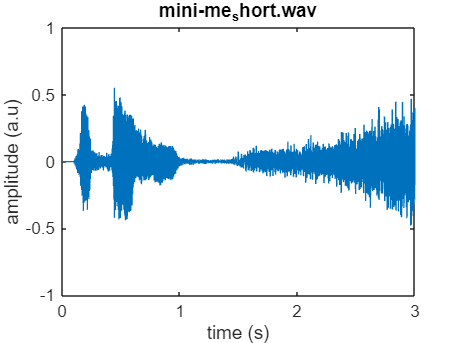

[y, fs, fn, t]= signals(input, type_signal, fs1, fs2, T, frequencies, fname, xlimTime, ylimAmplitude);

Do the frequency analysis: 

y_label = 'Magnitude (dB)'

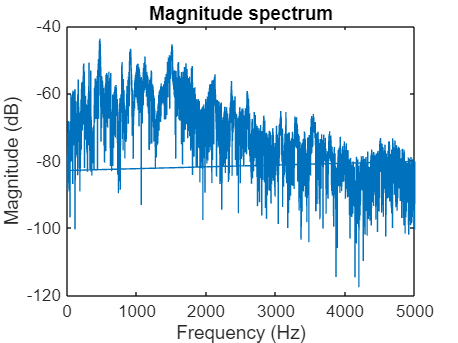

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


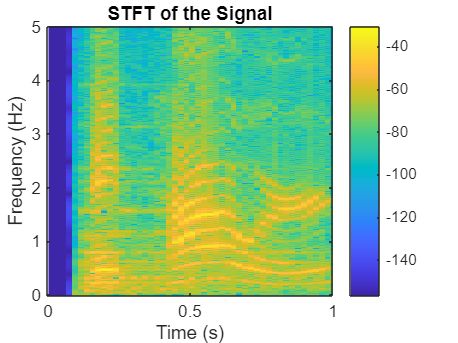

frequency(y, fs, spectral_resolution, window, xlimFreq, ylimFreq, yAxisType, xAxisType, overlapSTFT, 'magnitude_spectrum.pdf', 'STFT.pdf');

Filter the signal (shows and saves the magnitude/phase, pole/zero, impulse response, real/imaginary part of impulse response): 

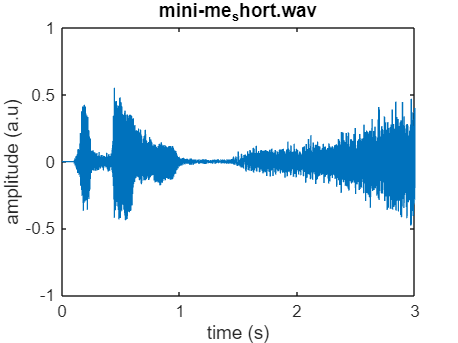

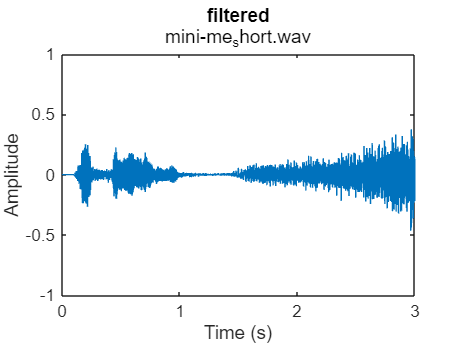

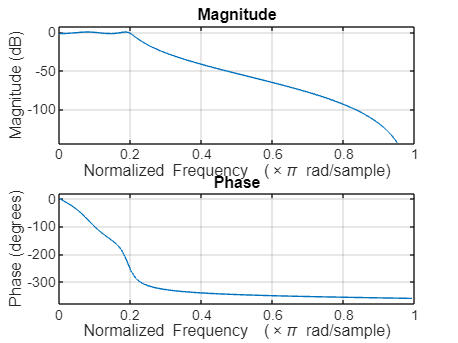

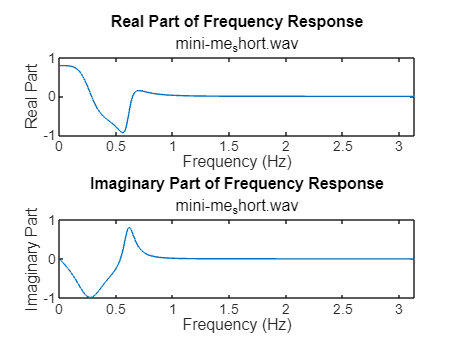

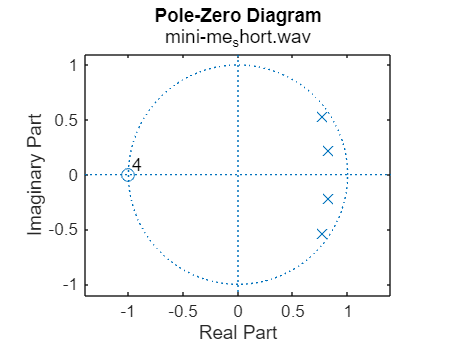

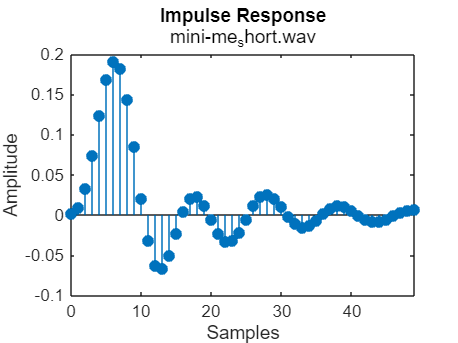

[t, filtered_signal, a, b]=filters(cutoffFrequencies, fn, filterType, method, type, order, y, fs, type_signal, input, fname, xlimTime, ylimAmplitude);

disp(a)

    1.0000   -3.1910    4.1494   -2.5703    0.6385



disp(b)

    0.0013    0.0053    0.0079    0.0053    0.0013



save('main.mat', 'a', 'b')

Frequency analysis of filtered signal: 

y_label = 'Magnitude (dB)'

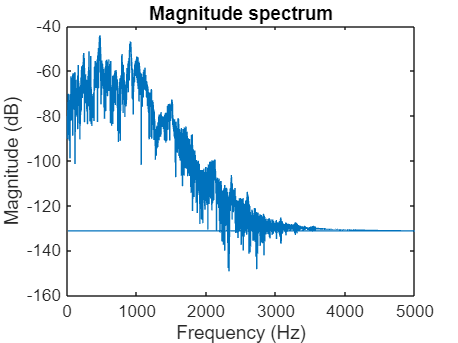

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


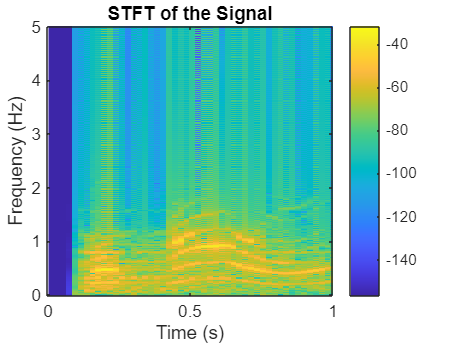

frequency(filtered_signal, fs, spectral_resolution, window, xlimFreq, ylimFreq, yAxisType, xAxisType, overlapSTFT, 'magnitude_spectrum_filtered.pdf', 'STFT_filtered.pdf' );